clear 
clc 
close all

% readmatrix('Flight_data\20231102_DynamicTest_01.xlsm')
table = readtable('Flight_data\Flightdata_20240714_01.xlsx')

table = 835×23 table
          UTC          Pack_count      q0           q1            q2             q3         RollRate     PitchRate     YawRate        Roll        Pitch         Yaw       FreeAccX    FreeAccY    FreeAccZ     Lat       Long     Height     VelX      VelY       VelZ     LoRaRSSI    LoRaSNR
    _______________    __________    _______    __________    ___________    ___________    _________    _________    __________    ________

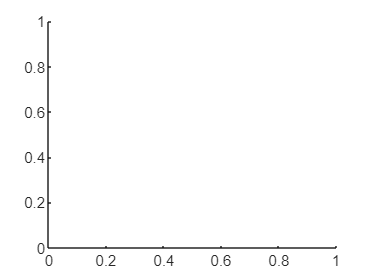

% now = yyyymmdd(datetime)
% a = datetime('now')
% time = a.Minute*60+a.Second;
% now = datenum(table.UTC(1))

%create figure
Rollplot = animatedline();
Pitchplot = animatedline();
Yawplot = animatedline();

Rollrateplot = animatedline();
Pitchrateplot = animatedline();
Yawrateplot = animatedline();

LLApositionplot = animatedline();


pastTime=0;
rmoutliers(table.Pack_count,'mean')

Error using  . 
To assign to or create a variable in a table, the number of rows must match the height of the table.


for i=1:length(table.UTC)
    
%     %     a = datetime('now');
%     % time = a.Minute*60+a.Second;
%     %     now = datenum(table.UTC)
%     %     plot(table.Pitch(i),table.Yaw(i))
%     %     drawnow
%     %     hold on
%     %     grid on
% 
%     % ss = (cell2mat(split(table.UTC{i}, ':')));
%     arr = sscanf(table.UTC{i},"%d:%d:%d:%d");
%     arr = [2024, 7, 14, arr'];
%     % for i = 1:4
%     %     arr = [arr, str2num(ss(i,:))];
%     % end
%     %
%     % time = datetime(arr(1), arr(2), arr(3), arr(4), arr(5), arr(6), arr(7))
%     time = arr(5)*60+arr(6);
%     if abs(table.Roll(i)) > 8
%         continue;
%     end
%     if abs(time) > 5000
%         continue;
%     end
%     if time < pastTime
%         continue;
%     end
% 
% 
%     addpoints(Rollplot,time,table.Roll(i))
%     addpoints(Pitchplot,time,table.Pitch(i))
%     addpoints(Yawplot,time,table.Yaw(i))
% 
%     addpoints(Rollrateplot,time,table.RollRate(i))
%     addpoints(Pitchrateplot,time,table.PitchRate(i))
%     addpoints(Yawrateplot,time,table.YawRate(i))
%     % drawnow limitrate
%     drawnow
%     if i ==100
%         clearpoints(Rollplot)
%     end
%     pastTime = time;
%     % hold on
%     % grid on
end

% ss = (cell2mat(split('20:46:08:22', ':')))
ss = sscanf('20:46:08:22',"%d:%d:%d:%d")
arr = [2024, 7, 14]
for i = 1:4
    arr = [arr, str2num(ss(i,:))];
end

datetime(arr(1), arr(2), arr(3), arr(4), arr(5), arr(6), arr(7))

syms y u s

sys = 1/(s^2-s+6);

$$sys = \frac{1}{s^{2}-s+6}$$

y = u*sys * 1/s;

$$y = \frac{s}{s^{2}-s+6}$$

$$ans = {\mathrm{e}}^{u/2}\,\left(\cos\left(\frac{\sqrt{23}\,u}{2}\right)+\frac{\sqrt{23}\,\sin\left(\frac{\sqrt{23}\,u}{2}\right)}{23}\right)$$

yt = ilaplace(y, s, u)
t = 0:0.1:10;
uIn = t>10;
subs()